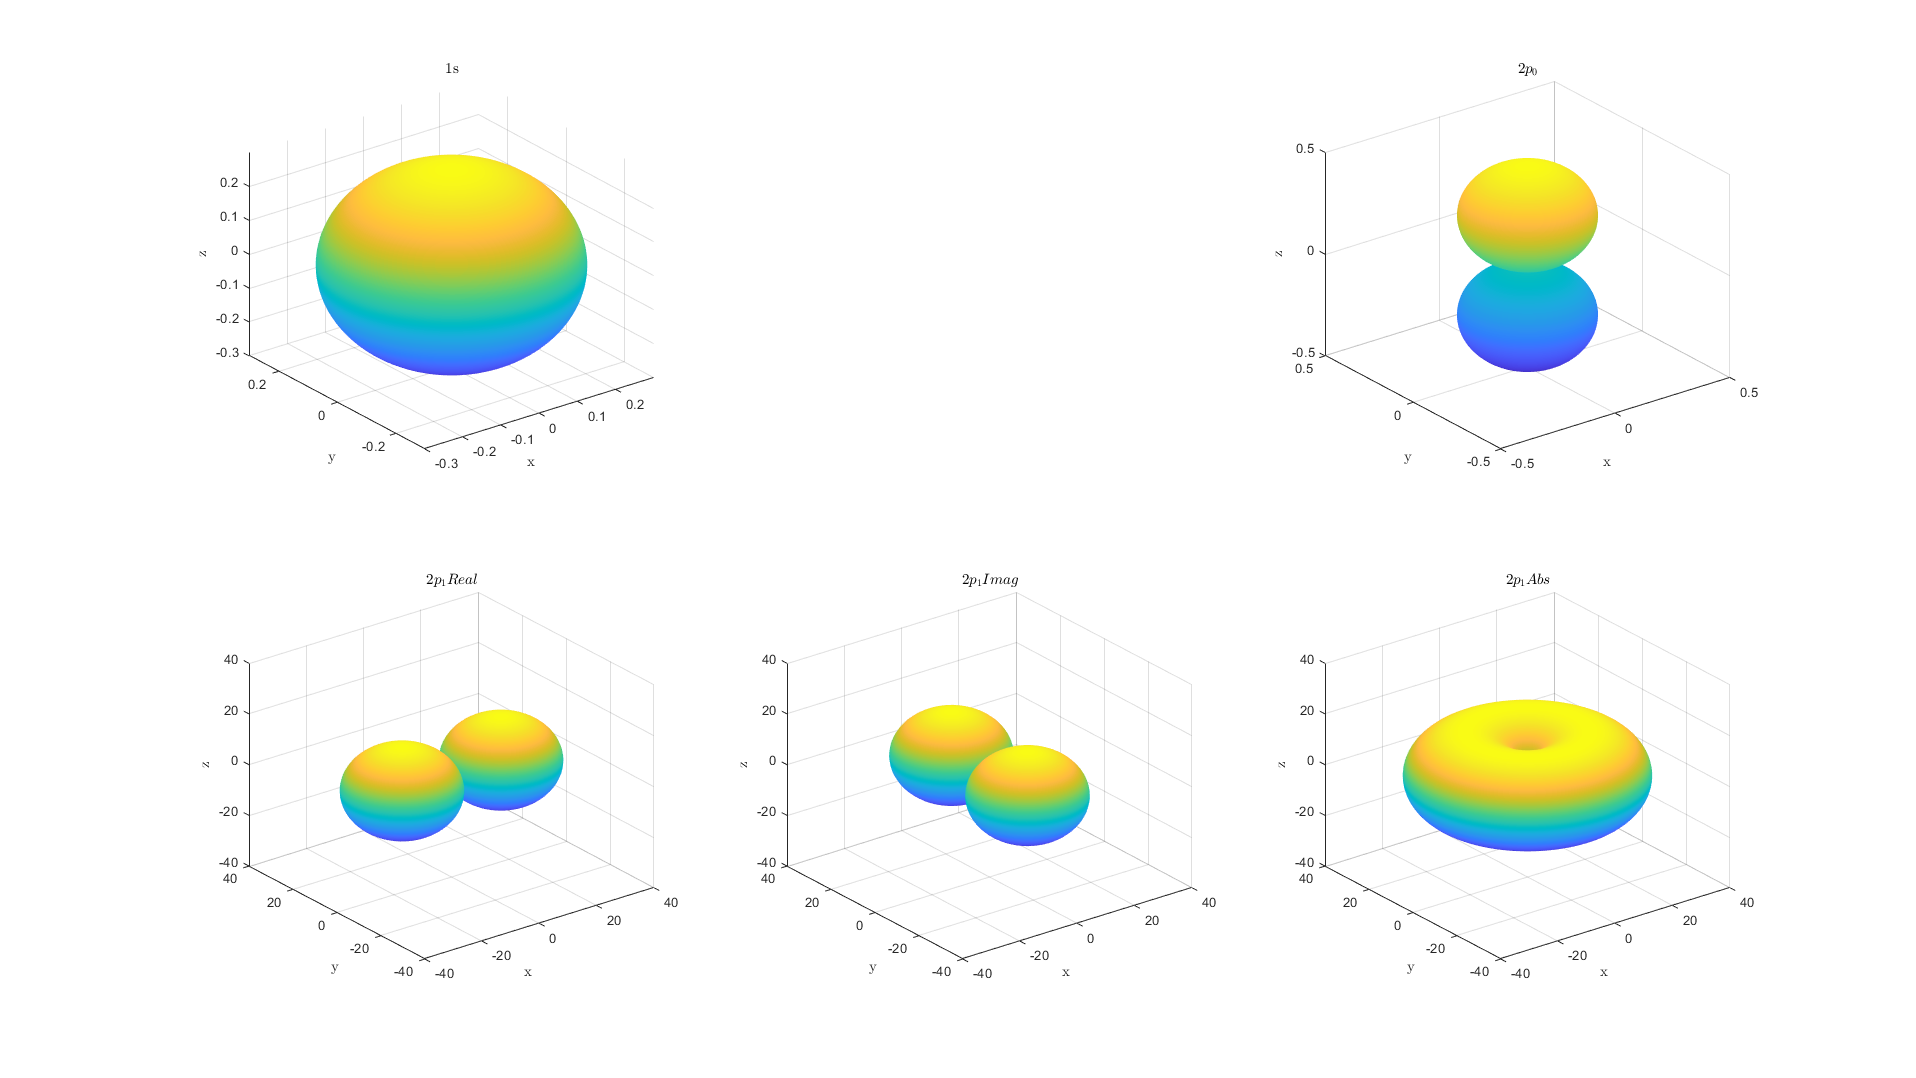

i=sqrt(-1);
a=0.529e-10;
A=1/sqrt(pi*a^3);
E=13.6*1.6e-19 ;
h=6.626e-34;
w=E*2*pi/h;

%1s 
ph=linspace(0, 2*pi);
tth=linspace(0, pi);

[Ph, Tth]=meshgrid(ph, tth);
%Tth=pi/2-Tth;
F=ones(100);
F=F*sqrt(1/(4*pi));

[X, Y, Z]=sph2cart(Ph, pi/2-Tth, F);
figure('Units', 'normalized', 'OuterPosition', [0 0 1 1]);
subplot(2, 3, 1), surf(X, Y, Z);
xlabel('x','Interpreter','latex');
ylabel('y','Interpreter','latex');
zlabel('z','Interpreter','latex');
title('1s', 'Interpreter','latex');
xlim([-0.3, 0.3]);
ylim([-0.3, 0.3]);
zlim([-0.3, 0.3]);
shading interp;

%2p0
clear F;
F=0.5*sqrt(3/pi)*cos(Tth);

[X, Y, Z]=sph2cart(Ph, pi/2-Tth, abs(F));

subplot(2, 3, 3), surf(X, Y, Z);
xlabel('x','Interpreter','latex');
ylabel('y','Interpreter','latex');
zlabel('z','Interpreter','latex');
title('$2p_0$', 'Interpreter','latex');
q=0.5;
xlim([-q, q]);
ylim([-q, q]);
zlim([-q, q]);
shading interp;


%2p1
clear F;
F=-0.5*sqrt(3/(2*pi))*sin(Tth)*exp(i*Ph);

[X, Y, Z]=sph2cart(Ph, pi/2-Tth, abs(real(F)));

subplot(2, 3, 4), surf(X, Y, Z);
xlabel('x','Interpreter','latex');
ylabel('y','Interpreter','latex');
zlabel('z','Interpreter','latex');
title('$2p_1 Real$', 'Interpreter','latex');
q=40;
xlim([-q, q]);
ylim([-q, q]);
zlim([-q, q]);
shading interp;

[X, Y, Z]=sph2cart(Ph, pi/2-Tth, abs(imag(F)));

subplot(2, 3, 5), surf(X, Y, Z);
xlabel('x','Interpreter','latex');
ylabel('y','Interpreter','latex');
zlabel('z','Interpreter','latex');
title('$2p_1 Imag$', 'Interpreter','latex');
q=40;
xlim([-q, q]);
ylim([-q, q]);
zlim([-q, q]);
shading interp;

[X, Y, Z]=sph2cart(Ph, pi/2-Tth, abs(F));

subplot(2, 3, 6), surf(X, Y, Z);
xlabel('x','Interpreter','latex');
ylabel('y','Interpreter','latex');
zlabel('z','Interpreter','latex');
title('$2p_1 Abs$', 'Interpreter','latex');
q=40;
xlim([-q, q]);
ylim([-q, q]);
zlim([-q, q]);
shading interp;


datestr(now)

ans = '10-Mar-2021 17:34:18'